# Plant Model

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Globals

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Export_Fig

%This toggles the exportfig commands throughout this file.  1 enables, 0
%disables.  We use this for nice PDF figures.

%This is the path for final figures.
figurePath = strcat(commonPath,'\Golden Figures\');

eftoggle = 1;


# Hybrid Model

%Model Setup
delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
%NOTE: In some versions of matlab, this command to set the simulink model
%to fixed step doesn't seem to work.  If you get an error about mismatched
%vector lengths in the next section, that means that the model is still on
%variable step mode.  You'll need to go in manually to the simulink model
%and change the settings to fixed step.
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize)
save_system(simName)

# rad to deg

r2deg = 180/pi;

# Typical Hybrid Response

This section is for generating some representative hybrid response figures at different switching thresholds.  The first part creates a single plot, and then the second part creates a three plot tiled layout.

No data is required for this section - all the data is generated here.

## Single Plot

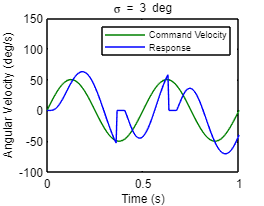

%Model Parameters
K_P = 15; %Smooth System Proportional Gain
K_I = 250; %Smooth System Integral Gain
switch_thresh = 3*(pi)/180; %Integrated error switching threshold (rad)
sac_time = 0.04; %Saccade execution time (s)
n_delay = 0.021; %Neurological delay (s)

%Input sin wave
sinin = pureSin(20,:);
V_in = [pureSinTime' sinin'];

%Run Simulation
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

%Generate Figure
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.75 2.1422])
pos = get(gcf,'pos');
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 150])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
xlabel('Time (s)','FontName','Arial','FontSize',9,'Color','k')
ylabel('Angular Velocity (deg/s)','FontName','Arial','FontSize',9)
legend('Command Velocity','Response','FontName','Arial','FontSize',7,'EdgeColor','k')
title('\sigma = 3 deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

%Saving Figure
set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\TypicalHybridResponse');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    %print(gcf,savePath,'-dpdf','-loose')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

## Tiled Plot (3)

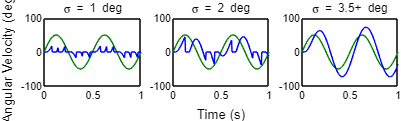

%Set up figure layout
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 7.25 2.1808])
pos = get(gcf,'pos');
tl = tiledlayout(1,3, 'Padding', 'none', 'TileSpacing', 'compact');

%Change switching threshold and run simulation
switch_thresh = 1*pi/180;
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

%Plot first tile
nexttile
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 100])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
title('\sigma = 1 deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

%Change switching threshold and run simulation
switch_thresh = 2*pi/180;
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

%Plot second tile
nexttile
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 100])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
title('\sigma = 2 deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

%Change switching threshold and run simulation
switch_thresh = 3.5*(pi)/180;
output = sim(simName,'SrcWorkspace','current');
out = output.V_out';

%Plot third tile
nexttile
plot(pureSinTime,sinin.*r2deg,'Color',[0 0.5 0],'LineWidth',0.75)
hold on
plot(pureSinTime,out.*r2deg,'b','LineWidth',0.75)
hold off
xlim([0 1])
ylim([-100 100])
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
title('\sigma = 3.5+ deg','FontName','Arial','FontSize',9,'Color','k','FontWeight','normal')
box on

%Labels applied to entire tiled layout
xlabel(tl,'Time (s)','FontName','Arial','FontSize',10,'Color','k')
ylabel(tl,'Angular Velocity (deg/s)','FontName','Arial','FontSize',10,'Color','k')

%Save figure
set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\HybridResponseCombine');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

%clear K_P K_I td switch_thresh sac_time n_delay sinin V_in

# Stability Plots

The nyquist plots do not require external data, but the three stability plots require data from the smooth stability code.

## Tiled Nyquist Plots setup

%Set up environment for tiled figures
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 7.25 3])
pos = get(gcf,'pos');
tl = tiledlayout(1,3, 'Padding', 'none', 'TileSpacing', 'compact');
xlabel(tl,'Real Axis','FontName','Arial','FontSize',10,'Color','k')
ylabel(tl,'Imaginary Axis','FontName','Arial','FontSize',10,'Color','k')

## Nyquist (Delay)

nexttile
%PI controller
Kp = 10;
Ki = 200;
C_tf = tf([Kp Ki],[1 0]); %Transfer function

%Delay
td = [0.04 0.058 0.065]; %Three delays
linecolors = [{'k'} {'b'} {'r'}];
hold on
w = logspace(0,11,1000);
for i = 1:size(td,2)
    %Delay (Pade approximation)
    [nump,denp]=pade(td(i),3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)  
end

%Add stability point
plot(-1,0,'r+')

%Cleanup limits and colors
xlim([-2,.25])
ylim([-1.5,1.5])
yline(0,':k');
xline(0,':k');
xline(-1,'r--');
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'Delay = 40 ms (Stable)','Delay = 58 ms (M. Stable)',...
    'Delay = 65 ms (Unstable)'},'FontName','Arial','FontSize',8,'EdgeColor','k','Location','northoutside')
title('K_P^* = 10, K_I^* = 200','FontName','Arial','FontSize',8,'Color','k','FontWeight','normal')
box on

## Nyquist (Proportional Gain)

nexttile
%PI controller
Kp = [10 38 45]; %Three different P gains
Ki = 200;

%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
hold on
w = logspace(0,11,1000);
for i = 1:size(Kp,2)
    C_tf = tf([Kp(i) Ki],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
end

%Add stability point
plot(-1,0,'r+')

%Cleanup limits and plots
xlim([-1.5,.5])
ylim([-1.5,1.5])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_P^* = 10 (Stable)','K_P^* = 38 (M. Stable)'...
    ,'K_P^* = 45 (Unstable)'},'FontName','Arial','FontSize',8,'EdgeColor','k','Location','northoutside')
title('K_I^* = 200, Delay = 40 ms','FontName','Arial','FontSize',8,'Color','k','FontWeight','normal')
box on

## Nyquist (Integral Gain)

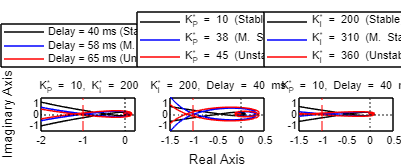

nexttile
%PI controller
Kp = 10;
Ki = [200 310 360]; %Three I gains

%Delay
td = 0.04;
linecolors = [{'k'} {'b'} {'r'}];
hold on
w = logspace(0,11,1000);
for i = 1:size(Ki,2)
    C_tf = tf([Kp Ki(i)],[1 0]);
    %Delay (Pade approximation)
    [nump,denp]=pade(td,3);
    d_tf = tf(nump,denp);
    
    %Open and Closed Loop Transfer Functions
    num = C_tf*G_plant;
    oltf = num*d_tf;
    den = (1 + oltf);
    cl_tf = num/den;
    
    %Nyquist
    [re,im,w] = nyquist(oltf,w);
    re = squeeze(re);
    im = squeeze(im);
    plot(re,im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)
    plot(re,-im,'Color',cell2mat(linecolors(i)),'LineWidth',0.75)   
end

%Add stability point
plot(-1,0,'r+')

%Cleanup plots
xlim([-1.5,.5])
ylim([-1.5,1.5])
yline(0,':')
xline(0,':')
xline(-1,'r--')
hold off
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
legend([ax.Children(9),ax.Children(7),ax.Children(5)],{'K_I^* = 200 (Stable)','K_I^* = 310 (M. Stable)'...
    ,'K_I^* = 360 (Unstable)'},'FontName','Arial','FontSize',8,'EdgeColor','k','Location','northoutside')
title('K_P^* = 10, Delay = 40 ms','FontName','Arial','FontSize',8,'Color','k','FontWeight','normal')
box on

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\NyquistCombined');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

## Delay Stability Surface

This requires data from the "Smooth System Stability" script.

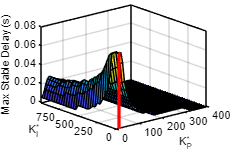

%Smooth Stability Data
inputPath = strcat(commonPath,'\Stability Sweep Data\');
latestStability = latestTimeParse(inputPath,'stabilitySweep');
load(latestStability)

%Interpolated surface
sf = fit([stabletip(:,1), stabletip(:,2)],stabletip(:,3),'cubicinterp');

%Setup figure properties
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.4 1.6])
pos = get(gcf,'pos');

set(gcf, 'Color', 'w');
plot(sf)
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial'; 
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 8;
ax.ZAxis.FontName = 'Arial';
ax.ZAxis.Color = 'k';
xlabel('K_P^*','FontName','Arial','FontSize',8)
ylabel('K_I^*','FontName','Arial','FontSize',8)
posx = ax.YLabel.Position;
ax.YLabel.Position = [posx(1:2) -0.01];
posy = ax.XLabel.Position;
ax.XLabel.Position = [posy(1:2) -0.01];
zlabel('Max Stable Delay (s)','FontName','Arial','FontSize',8)
box on
hold on
r=4;

%Add pickoff point for D. melanogaster
[X,Y,Z] = cylinder(r,50);
X = X + 10;
Z = Z*0.08;
h=surf(X,Y,Z,'FaceColor',[1 0 0],'EdgeColor',[1 0 0]);

%Setup limits
xlim([0 400])
ylim([0 1000])
zlim([0 0.08])

%Cleanup ticks
p = get(gca,'Position');
set(gca,'Position',[p(1) p(2)+0.05 p(3) p(4)]);
xticks([0 100 200 300 400])
yticks([0 250 500 750])
xtickangle(0)
ytickangle(0)

%Save image
set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

view(-40,25)
savePath =strcat(figurePath,'\Smooth Stability\MaxStableDelayLeft');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

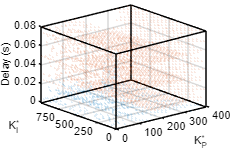


%Stability point cloud
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.4 1.6])
pos = get(gcf,'pos');

%Plot stable and unstable points as scatter
set(gcf, 'Color', 'w');
stable = stable(1:10:end,:);
unstable = unstable(1:10:end,:);
scatter3(stable(:,1), stable(:,2), stable(:,3),0.01,'o')
hold on
scatter3(unstable(:,1), unstable(:,2), unstable(:,3),0.01,'o')

%Cleanup plot
ax = gca;
ax.BoxStyle ='full';
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
ax.ZAxis.FontSize = 8;
ax.ZAxis.FontName = 'Arial';
ax.ZAxis.Color = 'k';
xlabel('K_P^*','FontName','Arial','FontSize',8)
ylabel('K_I^*','FontName','Arial','FontSize',8)
posx = ax.YLabel.Position;
ax.YLabel.Position = [posx(1:2) -0.01];
posy = ax.XLabel.Position;
ax.XLabel.Position = [posy(1:2) -0.01];
zlabel('Delay (s)','FontName','Arial','FontSize',8)
box on
xlim([0 400])
ylim([0 1000])
zlim([0 0.08])

%Cleanup ticks
p = get(gca,'Position');
set(gca,'Position',[p(1) p(2)+0.05 p(3) p(4)]);
xticks([0 100 200 300 400])
yticks([0 250 500 750])
xtickangle(0)
ytickangle(0)

%Save image
set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

view(-40,25)
savePath =strcat(figurePath,'\Smooth Stability\StabilityCloud');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

## 0.021 Delay Slice

This pulls off a slice of the surface at the D. melanogaster point for neurological delay.

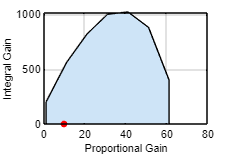

slicePath = strcat(commonPath,'\Stability Sweep Data\');
latestSlice = latestTimeParse(slicePath,'02DelaySlice');
load(latestSlice)
clear slicePath latestSlice
xdata = stableSliceMax(:,1);
ydata = stableSliceMax(:,2);

%Setup figure
figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 2.4 1.6])
pos = get(gcf,'pos');

%Color the regiona and add the gain point for D. melanogaster
a = area(stableSliceMax(:,1),stableSliceMax(:,2),'FaceColor','#CEE4F7');
ax = gca;
set(gcf, 'Color', 'w');
ax.XAxis.FontSize = 8;
ax.XAxis.FontName = 'Arial';
ax.XAxis.Color = 'k';
ax.YAxis.FontSize = 8;
ax.YAxis.FontName = 'Arial';
ax.YAxis.Color = 'k';
xlabel('Proportional Gain','FontName','Arial','FontSize',8)
ylabel('Integral Gain','FontName','Arial','FontSize',8)
%title('Stable Region for Delay of 40ms','FontName','Arial','FontSize',22,'FontWeight','bold')
grid on
hold on
plot(10,0.1,'.r','MarkerSize',15)
xlim([0 80])

%Save figure
set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

savePath =strcat(figurePath,'\Smooth Stability\DelaySlice');
if eftoggle == 1
    %export_fig (savePath,'-pdf')
    exportgraphics(gcf,strcat(savePath,'.pdf'))
end

# Hybrid and Smooth Swept Performance

This section requires data from the HybridPerformance code.

## Slice Performance plots

clearvars -except commonPath
%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');

%This part is just to get the structure to populate an empty version for
%filling. 
latestSweep = latestTimeParse(inputPath,'megaSweep_1'); 
load(latestSweep)
sweepData = repmat(sweepData(1,1),size(sweepData,1),size(sweepData,1),size(sweepData,2));

%Load data from each segmented file
for i = 1:1:size(sweepData,1)
   tic
   latestSweep = latestTimeParse(inputPath,strcat('megaSweep_',num2str(i))); 
   T = load(latestSweep);
   sweepData(i,:,:) = T.sweepData;
   clear T
   toc
end

Elapsed time is 0.098589 seconds.
Elapsed time is 0.100199 seconds.
Elapsed time is 0.099321 seconds.
Elapsed time is 0.099914 seconds.
Elapsed time is 0.102217 seconds.
Elapsed time is 0.100459 seconds.
Elapsed time is 0.099575 seconds.
Elapsed time is 0.100795 seconds.
Elapsed time is 0.100659 seconds.
Elapsed time is 0.100484 seconds.
Elapsed time is 0.099124 seconds.


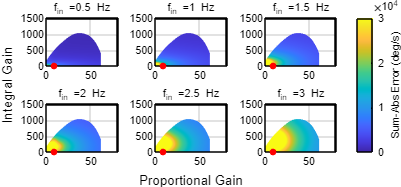

eftoggle = 1;
clear inputPath latestSweep

%Generate the smooth and hybrid slice performance plots (six figures each)
SlicePerformance(sweepData,commonPath,'sSAE',0,eftoggle,0)

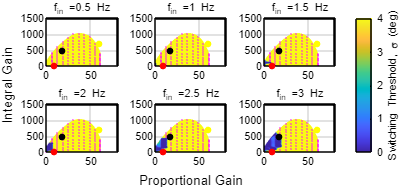

sigmaInd = 4;
SlicePerformance(sweepData,commonPath,'hSigmaSAEPurp',sigmaInd,eftoggle,25)

## Detailed look at Performance at KP* = 10, KI*  = 0

clearvars -except commonPath

figure('Renderer', 'painters','units','inches')
pos = get(gcf,'pos');
set(gcf,'pos',[pos(1) pos(2) 7.25 3.3833])
pos = get(gcf,'pos');
tl = tiledlayout(2,3,'Padding','none', 'TileSpacing', 'compact');

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');
latestSweep = latestTimeParse(inputPath,'megaSweep10_1'); 
load(latestSweep)

%Chosen Switching Threshold
sigs = [0.5 1 3 6].*(pi/180);

%Generate surface plot 1 and set view
nexttile
[ftraces1,saetraces1] = fsigmaplot(sweepData,switchThresh,sinfreqsDecimate,sigs);
view(-35,20)

## Detailed look at Performance at KP* = 18, KI*  = 500

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');
latestSweep = latestTimeParse(inputPath,'megaSweep18_1'); 
load(latestSweep)

%Generate surface plot 2
nexttile
[ftraces2,saetraces2] = fsigmaplot(sweepData,switchThresh,sinfreqsDecimate,sigs);
view(-35,20)


## Detailed look at Performance at KP* = 60, KI*  = 700

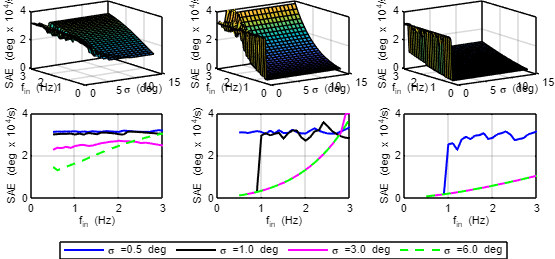

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');
latestSweep = latestTimeParse(inputPath,'megaSweep60_1'); 
load(latestSweep)
eftoggle = 1;

%Generate Surface plot 3
nexttile
[ftraces3,saetraces3] = fsigmaplot(sweepData,switchThresh,sinfreqsDecimate,sigs);
view(-35,20)

%Generate three line plots
nexttile
ax1 = fsae2d(ftraces1,saetraces1,sigs,0);
nexttile
ax2 = fsae2d(ftraces2,saetraces2,sigs,0);
nexttile
ax3 = fsae2d(ftraces3,saetraces3,sigs,0);

%Create legend and save figure.
lg  = legend(ax1,'Orientation','Horizontal','NumColumns',5,'FontName','Arial','FontSize',8,'EdgeColor','k'); 
lg.Layout.Tile = 'South'; % <-- Legend placement with tiled layout


basepath = strcat(commonPath,'\Golden Figures\Hybrid Performance\');
savePath = strcat(basepath,'hSAEdet','.pdf');

set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

if eftoggle == 1
    %export_fig (savePath,'-pdf','-nocrop')
    exportgraphics(gcf,savePath)
end

Error using exportgraphics
The value of 'destination' is invalid. Unable to create output file 'C:\Users\davis287\Desktop\Smooth_Saccade_Simulation\Common Files\Golden Figures\Hybrid
Performance\hSAEdet.pdf', No such file or directory.

# Selected points for Discussion

This requires data generated by the HybridPerformance script

clearvars -except commonPath
%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.
inputPath = strcat(commonPath,'\Hybrid Performance Results\SweepTemp\');

%This part is just to get the structure to populate an empty version for
%filling.
latestSweep = latestTimeParse(inputPath,'megaSweep_disc_1'); 
load(latestSweep)
sweepData = repmat(sweepData(1,1),size(sweepData,1),size(sweepData,1),size(sweepData,2));

%Load in each section of the data set
for i = 1:1:size(sweepData,1)
   tic
   latestSweep = latestTimeParse(inputPath,strcat('megaSweep_disc_',num2str(i))); 
   T = load(latestSweep);
   sweepData(i,:,:) = T.sweepData;
   clear T
   toc
end

Elapsed time is 0.043035 seconds.
Elapsed time is 0.043105 seconds.


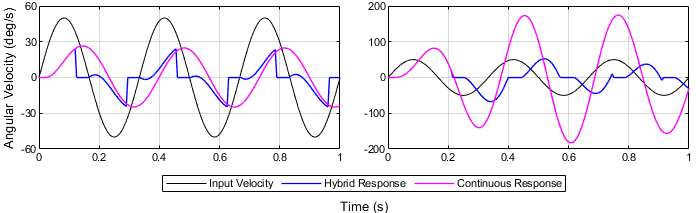

clear inputPath latestSweep

%Create the two response curves at the chosen sample points.
[pos] = responseCurves(sweepData,...
    Ki,Kp,switchThresh,sinfreqsDecimate,pureSinTime,[10 10],[0 500],[0.05 0.04],[3 6]);
basepath = strcat(commonPath,'\Golden Figures\Hybrid Performance\');
savePath = strcat(basepath,'disctraces','.pdf');
eftoggle = 1;

%Save figure
set(gcf,'PaperPositionMode','Auto','PaperUnits','Inches','PaperSize',[pos(3), pos(4)])

if eftoggle == 1
    %export_fig (savePath,'-pdf','-nocrop')
    exportgraphics(gcf,savePath)
end

# Hybrid Stability

This section requires data from the HybridStability Script

Elapsed time is 0.147872 seconds.


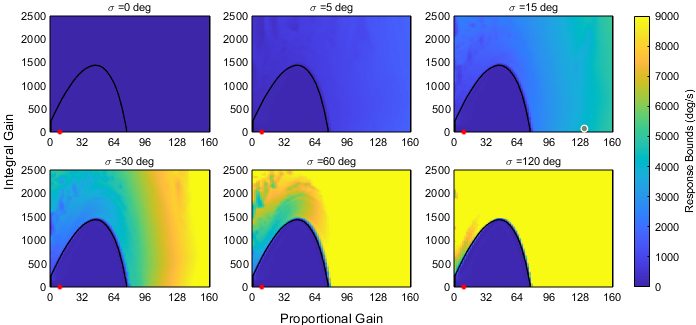

clearvars -except commonPath
eftoggle = 1;

%Load portion Hybrid Stability data (stiff section)
hStabPath = strcat(commonPath,'\Hybrid Stability Results\');
latestStab = latestTimeParse(hStabPath,'stabSweepstiff');

%This weirdness is all a trick to reduce data in memory by getting rid of
%excess data fields.
tempFile = matfile(latestStab);
stabData4= tempFile.stabData(:,4);
stabData5= tempFile.stabData(:,5);
stabDataABS = abs(stabData5-stabData4);
clear stabData4 stabData5
stabDataSmall = tempFile.stabData(:,1:3);
stabDataStiffFinal = [stabDataSmall stabDataABS];
clear stabDataSmall stabDataABS
sigmaS = tempFile.sigma;

%Load portion Hybrid Stability data (nonstiff section)
latestStab = latestTimeParse(hStabPath,'stabSweeploose');
tempFile = matfile(latestStab);
stabData4= tempFile.stabData(:,4);
stabData5= tempFile.stabData(:,5);
stabDataABS = abs(stabData5-stabData4);
clear stabData4 stabData5
stabDataSmall = tempFile.stabData(:,1:3);
stabDataLooseFinal = [stabDataSmall stabDataABS];
clear stabDataSmall stabDataABS
sigma = [tempFile.sigma sigmaS];

%Organize data into one set
inc = 1;
stabDatafFinal = stabDataStiffFinal;
for i =1:6:(size(stabDataStiffFinal,1)+size(stabDataLooseFinal,1))
    if i == 1
        stabDatafFinal = [stabDataLooseFinal(inc,:) ; stabDatafFinal];    
    else
        stabDatafFinal = [stabDatafFinal(1:(i-1),:) ; stabDataLooseFinal(inc,:) ; stabDatafFinal(i:end,:)]; 
    end
    inc = inc + 1;
end

%Choose switching thresholds and plot
sigs = (pi/180)*[0.02 5 15 30 60 120];
stabPlot(stabDatafFinal,sigs,sigma,commonPath,eftoggle);

# Bode Plots for margins

This does not require pre-generated data.  It is all done here.

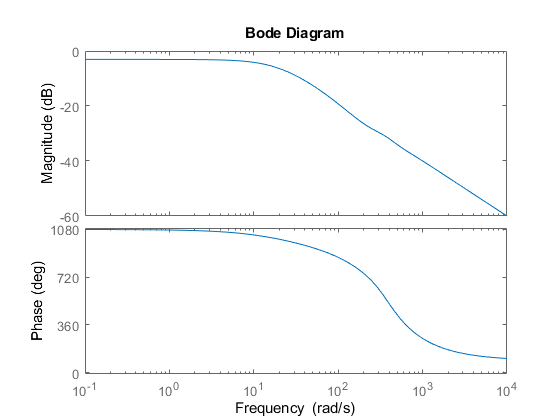

clearvars -except commonPath
plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant);
eftoggle = 1;

%PI controller (low gain)
Kp = 10;
Ki = 0;

C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td =0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = d_tf*C_tf*G_plant;
den = (1 + num);
cl_tf = num/den;
num=minreal(num);

%Bode plot for low gain system
[mag1,phase1,wout1] = bode(num);
figure
bode(cl_tf)

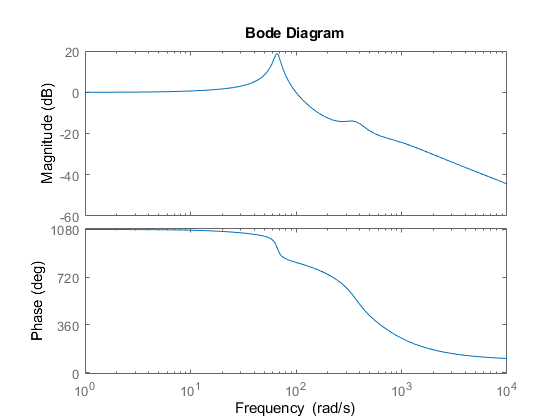

[Gm1,Pm1,Wcg1,Wcp1] = margin(num);

%PI controller (high gain)
Kp = 60;
Ki = 700;

C_tf = tf([Kp Ki],[1 0]);

%Delay (Pade approximation)
td =0.021;
[nump,denp]=padeWrap(td);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = d_tf*C_tf*G_plant;
den = (1 + num);
cl_tf = num/den;
num = minreal(num);

%Bode plot for high gain system
[mag2,phase2,wout2] = bode(num);
figure
bode(cl_tf)

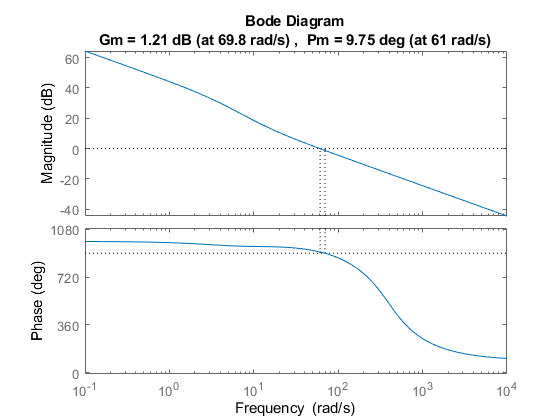

[Gm2,Pm2,Wcg2,Wcp2] = margin(num);
figure
margin(num)

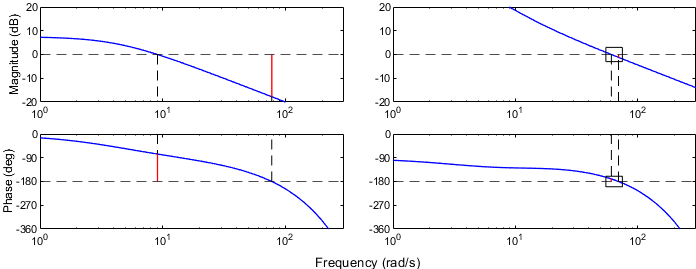

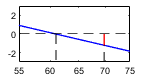

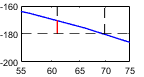

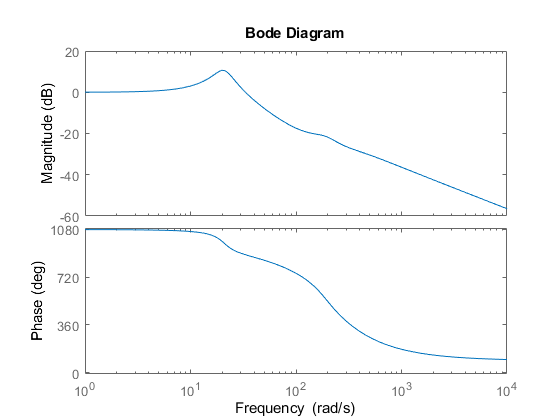


%Inset plot coordinates
insetg = [55 -3 20 6]; %34.5 to 40 x , -1.25 to 0.5 y
insetp = [55 -200 20 40]; %34.5 to 40 x , 897 to 915 y

%Create margin plots using the bode plot data
marginplots(mag1,phase1-1080,wout1,Gm1,Pm1,Wcg1,Wcp1,mag2,phase2-1080,wout2,Gm2,Pm2,Wcg2,Wcp2,...
    insetg,insetp,commonPath,eftoggle)